clear
close all
clc

在纸上手工标记子图序号，录入

pos = [26, 19, 18, 17, 24, 27, 13, 11, 9, 23, 28, 7, 4, 1, 22];

开始绘图

figure;
id = 1;

先由小到大遍历模长

for r = 0.8:0.2:1.2

再由0到pi遍历辐角

    for theta = 0:pi/4:pi

定义极点，若不在实轴上则定义一对共轭极点

        p = r*exp(1j*theta);
        if theta ~= 0 && theta ~= pi
            p = [p;p'];
        end

将极点转换为传递函数分子、分母多项式系数

        [b,a] = zp2tf([],p,1);

计算单位样值响应，绘图

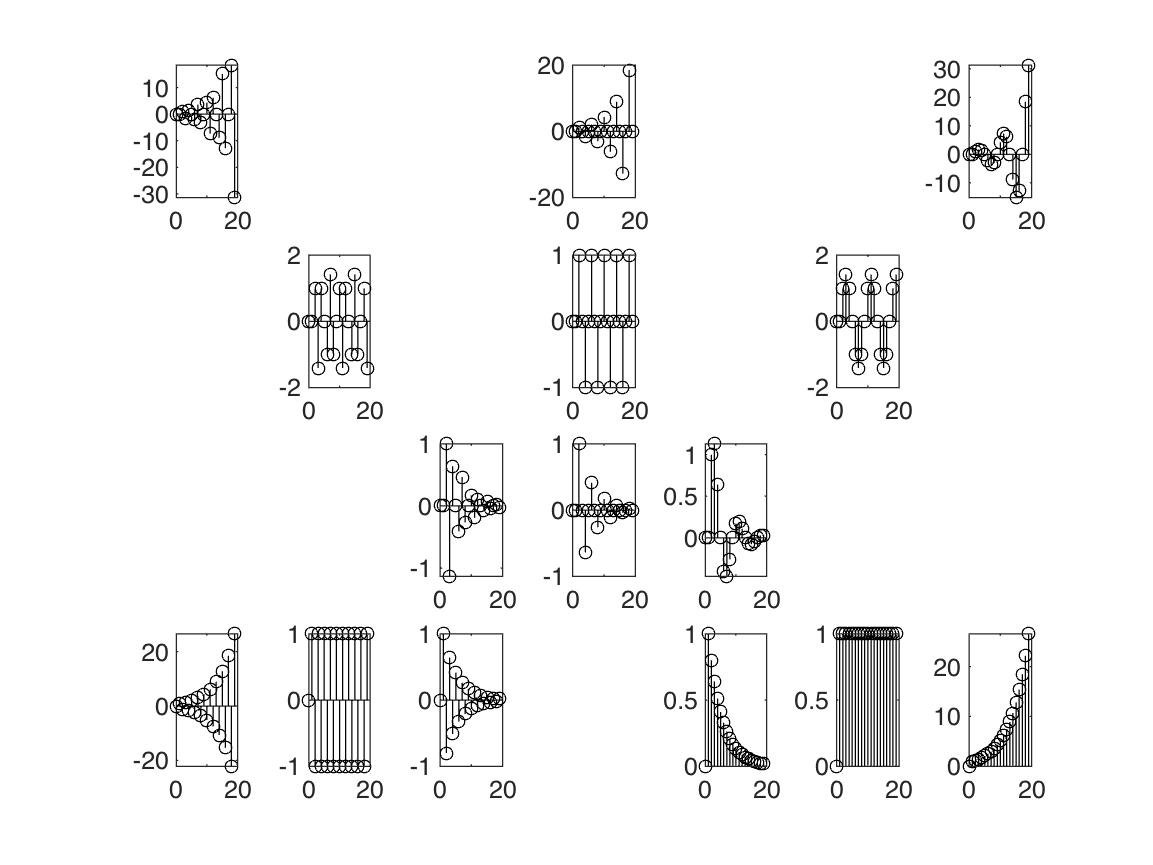

        subplot(4,7,pos(id));
        [h,t] = impz(b,a,20);
        stem(t,h,'k-','MarkerSize',5);
        id = id + 1;
    end
end